# Examples for using the `delete_data_points` function.

Copyright © 2022 Tamas Kis

## Data Set for All Examples

We create a data set $\mathbf{y}$ vs. $\mathbf{x}$ where $\mathbf{x}$ stores $x$-values between (and including) -5 and 5, separated by 0.5, and where the $i^{\textrm{th}}$ $y$-value is given by $y_i =x_i^2 -5$.

x = -5:0.5:5;
y = x.^2-5;

## Example #1: Delete all data points where x > 0.

First, we form the new data set by deleting all the data points where $x>0$.

[x_new,y_new] = delete_data_points(x,y,x>0);

Next, we plot the two data sets to verify that the correct data points were deleted.

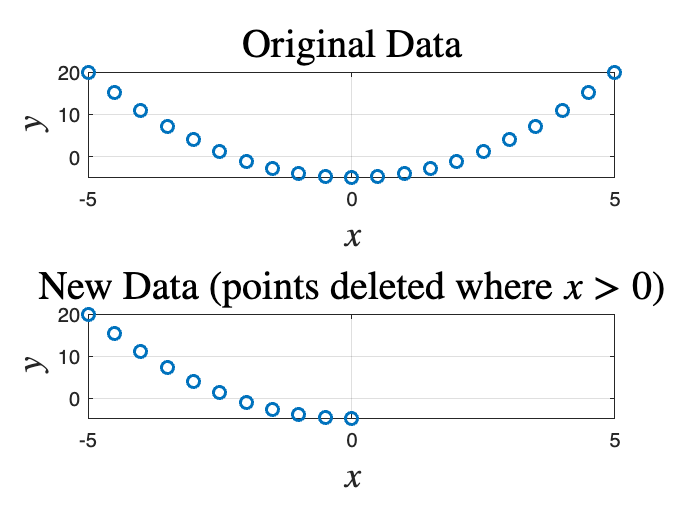

% initializes figure
figure;

% original data
subplot(2,1,1);
plot(x,y,'o','LineWidth',1.5);
grid on;
xlim([-5,5]);
ylim([-5,20]);
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$y$','Interpreter','latex','FontSize',18);
title('Original Data','Interpreter','latex','FontSize',20);

% new data
subplot(2,1,2);
plot(x_new,y_new,'o','LineWidth',1.5);
grid on;
xlim([-5,5]);
ylim([-5,20]);
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$y$','Interpreter','latex','FontSize',18);
title("New Data (points deleted where $x>0$)",'Interpreter','latex',...
    'FontSize',20);

## Example #2: Delete all data points where x < y.

First, we form the new data set by deleting all the data points where $x<y$.

[x_new,y_new] = delete_data_points(x,y,x<y);

Next, we plot the two data sets to verify that the correct data points were deleted.

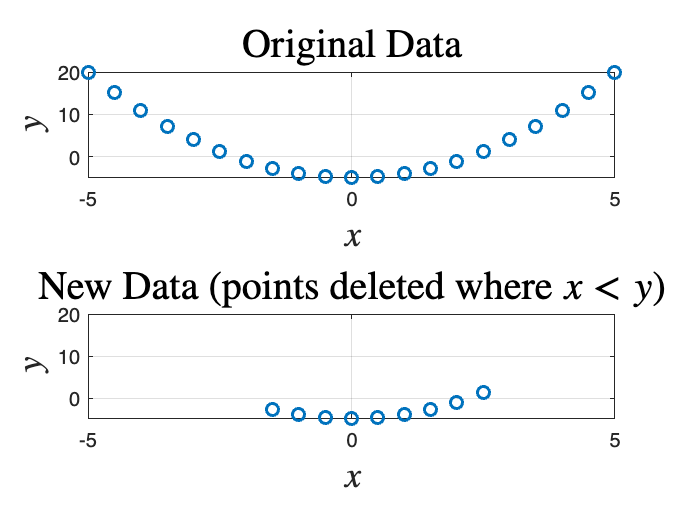

% initializes figure
figure;

% original data
subplot(2,1,1);
plot(x,y,'o','LineWidth',1.5);
grid on;
xlim([-5,5]);
ylim([-5,20]);
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$y$','Interpreter','latex','FontSize',18);
title('Original Data','Interpreter','latex','FontSize',20);

% new data
subplot(2,1,2);
plot(x_new,y_new,'o','LineWidth',1.5);
grid on;
xlim([-5,5]);
ylim([-5,20]);
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$y$','Interpreter','latex','FontSize',18);
title("New Data (points deleted where $x<y$)",'Interpreter','latex',...
    'FontSize',20);

## Example #3: Delete all data points where x < y AND -4 ≥ y.

We form an intermediate data set by first deleting all the data points where $x<y$.

[x_int,y_int] = delete_data_points(x,y,x<y);

Next, we form the new data set by deleting all the data points (from the intermediate data set) where $-4\ge y$.

[x_new,y_new] = delete_data_points(x_int,y_int,-4>=y_int);

Finally, we plot the two data sets to verify that the correct data points were deleted.

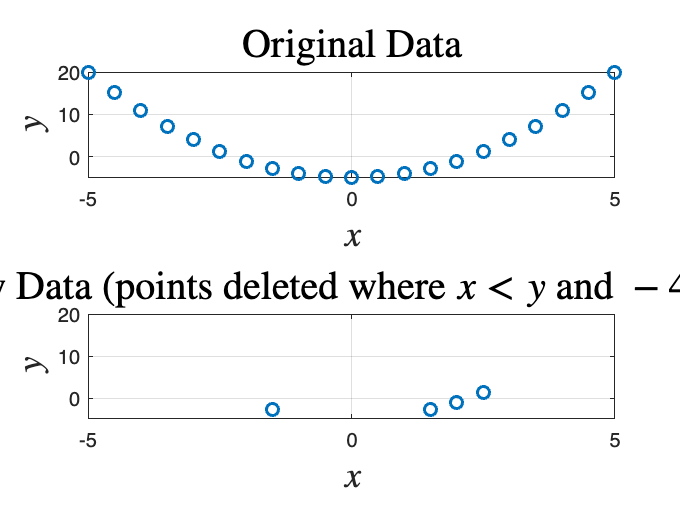

% initializes figure
figure;

% original data
subplot(2,1,1);
plot(x,y,'o','LineWidth',1.5);
grid on;
xlim([-5,5]);
ylim([-5,20]);
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$y$','Interpreter','latex','FontSize',18);
title('Original Data','Interpreter','latex','FontSize',20);

% new data
subplot(2,1,2);
plot(x_new,y_new,'o','LineWidth',1.5);
grid on;
xlim([-5,5]);
ylim([-5,20]);
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$y$','Interpreter','latex','FontSize',18);
title("New Data (points deleted where $x<y$ and $-4\geq y$)",'Interpreter',...
'latex','FontSize',20);

## Example #4: Delete all data points where xy < 0.

First, we form the new data set by deleting all the data points where $\textrm{xy}<0$.

[x_new,y_new] = delete_data_points(x,y,x.*y<0);

Next, we plot the two data sets to verify that the correct data points were deleted.

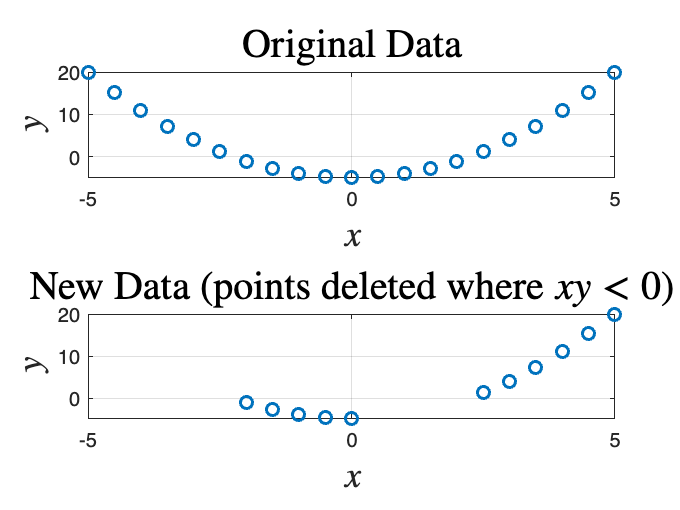

% initializes figure
figure;

% original data
subplot(2,1,1);
plot(x,y,'o','LineWidth',1.5);
grid on;
xlim([-5,5]);
ylim([-5,20]);
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$y$','Interpreter','latex','FontSize',18);
title('Original Data','Interpreter','latex','FontSize',20);

% new data
subplot(2,1,2);
plot(x_new,y_new,'o','LineWidth',1.5);
grid on;
xlim([-5,5]);
ylim([-5,20]);
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$y$','Interpreter','latex','FontSize',18);
title("New Data (points deleted where $xy<0$)",'Interpreter','latex',...
    'FontSize',20);

## Example #5: Keep all data points where xy < 0.

Instead of deleting all data points where $\textrm{xy}<0$ (as in Example #4), we now want to *keep* all data points where $\textrm{xy}<0$. To do this, we can use the exact same code as in Example #4, but just negating the logical expression.

[x_new,y_new] = delete_data_points(x,y,~(x.*y<0));

Plotting the two data sets to verify that the correct data points were kept,

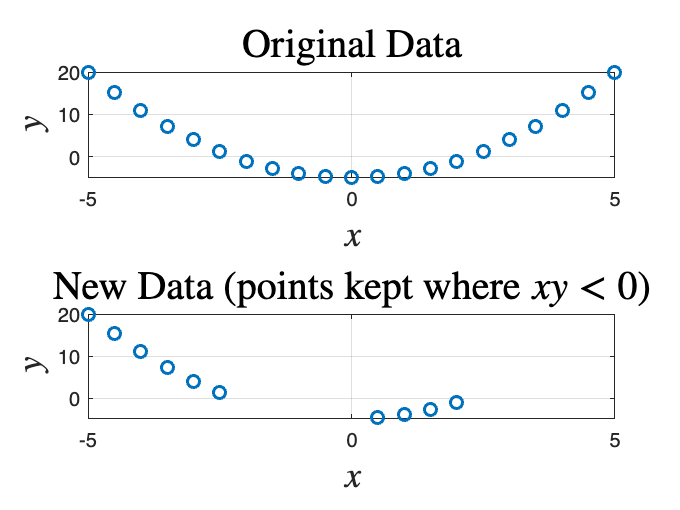

% initializes figure
figure;

% original data
subplot(2,1,1);
plot(x,y,'o','LineWidth',1.5);
grid on;
xlim([-5,5]);
ylim([-5,20]);
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$y$','Interpreter','latex','FontSize',18);
title('Original Data','Interpreter','latex','FontSize',20);

% new data
subplot(2,1,2);
plot(x_new,y_new,'o','LineWidth',1.5);
grid on;
xlim([-5,5]);
ylim([-5,20]);
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$y$','Interpreter','latex','FontSize',18);
title("New Data (points kept where $xy<0$)",'Interpreter','latex',...
    'FontSize',20);